# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 20-Apr-2025 09:59:37

## Load Network Parameters

Load network parameters like weights, biases, or layers unsupported for network code generation from the stored parameters file.

params = load("/Users/jakecolwell/Library/CloudStorage/OneDrive-TheOhioStateUniversity/000 Intracorporeal 3D Printing/MATLAB/BayesianOptimization_ConformalPrinting/Data/M4/params_2025_04_20__09_59_11.mat");

## Create dlnetwork

Create the dlnetwork variable to contain the network layers.

net = dlnetwork;

## Add Layer Branches

Add branches to the dlnetwork. Each branch is a linear array of layers.

tempNet = [
    imageInputLayer([128 128 1],"Name","imageinput","Mean",params.imageinput.Mean)
    convolution2dLayer([3 3],16,"Name","conv","Padding","same","Bias",params.conv.Bias,"Weights",params.conv.Weights)
    batchNormalizationLayer("Name","batchnorm","Offset",params.batchnorm.Offset,"Scale",params.batchnorm.Scale,"TrainedMean",params.batchnorm.TrainedMean,"TrainedVariance",params.batchnorm.TrainedVariance)
    reluLayer("Name","relu")
    convolution2dLayer([3 3],16,"Name","conv_1","Padding","same","Stride",[2 2],"Bias",params.conv_1.Bias,"Weights",params.conv_1.Weights)
    batchNormalizationLayer("Name","batchnorm_1","Offset",params.batchnorm_1.Offset,"Scale",params.batchnorm_1.Scale,"TrainedMean",params.batchnorm_1.TrainedMean,"TrainedVariance",params.batchnorm_1.TrainedVariance)
    reluLayer("Name","relu_1")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([3 3],16,"Name","conv_2","Padding","same","Stride",[2 2],"Bias",params.conv_2.Bias,"Weights",params.conv_2.Weights)
    batchNormalizationLayer("Name","batchnorm_2","Offset",params.batchnorm_2.Offset,"Scale",params.batchnorm_2.Scale,"TrainedMean",params.batchnorm_2.TrainedMean,"TrainedVariance",params.batchnorm_2.TrainedVariance)
    reluLayer("Name","relu_2")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([3 3],32,"Name","conv_3","Padding","same","Stride",[2 2],"Bias",params.conv_3.Bias,"Weights",params.conv_3.Weights)
    batchNormalizationLayer("Name","batchnorm_3","Offset",params.batchnorm_3.Offset,"Scale",params.batchnorm_3.Scale,"TrainedMean",params.batchnorm_3.TrainedMean,"TrainedVariance",params.batchnorm_3.TrainedVariance)
    reluLayer("Name","relu_3")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([3 3],64,"Name","conv_4","Padding","same","Stride",[2 2],"Bias",params.conv_4.Bias,"Weights",params.conv_4.Weights)
    batchNormalizationLayer("Name","batchnorm_4","Offset",params.batchnorm_4.Offset,"Scale",params.batchnorm_4.Scale,"TrainedMean",params.batchnorm_4.TrainedMean,"TrainedVariance",params.batchnorm_4.TrainedVariance)
    reluLayer("Name","relu_7")
    transposedConv2dLayer([3 3],32,"Name","transposed-conv_3","Cropping","same","Stride",[2 2],"Bias",params.transposed_conv_3.Bias,"Weights",params.transposed_conv_3.Weights)
    batchNormalizationLayer("Name","batchnorm_5","Offset",params.batchnorm_5.Offset,"Scale",params.batchnorm_5.Scale,"TrainedMean",params.batchnorm_5.TrainedMean,"TrainedVariance",params.batchnorm_5.TrainedVariance)
    reluLayer("Name","relu_8")];
net = addLayers(net,tempNet);

tempNet = [
    depthConcatenationLayer(2,"Name","depthcat")
    transposedConv2dLayer([3 3],16,"Name","transposed-conv","Cropping","same","Stride",[2 2],"Bias",params.transposed_conv.Bias,"Weights",params.transposed_conv.Weights)
    batchNormalizationLayer("Name","batchnorm_6","Offset",params.batchnorm_6.Offset,"Scale",params.batchnorm_6.Scale,"TrainedMean",params.batchnorm_6.TrainedMean,"TrainedVariance",params.batchnorm_6.TrainedVariance)
    reluLayer("Name","relu_4")];
net = addLayers(net,tempNet);

tempNet = [
    depthConcatenationLayer(2,"Name","depthcat_1")
    transposedConv2dLayer([3 3],16,"Name","transposed-conv_1","Cropping","same","Stride",[2 2],"Bias",params.transposed_conv_1.Bias,"Weights",params.transposed_conv_1.Weights)
    batchNormalizationLayer("Name","batchnorm_7","Offset",params.batchnorm_7.Offset,"Scale",params.batchnorm_7.Scale,"TrainedMean",params.batchnorm_7.TrainedMean,"TrainedVariance",params.batchnorm_7.TrainedVariance)
    reluLayer("Name","relu_5")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([3 3],1,"Name","conv_8","Padding","same","Bias",params.conv_8.Bias,"Weights",params.conv_8.Weights)
    resize2dLayer("Name","resize-scale_1","GeometricTransformMode","half-pixel","Method","nearest","NearestRoundingMode","round","Scale",[4 4])];
net = addLayers(net,tempNet);

tempNet = [
    depthConcatenationLayer(2,"Name","depthcat_2")
    transposedConv2dLayer([3 3],1,"Name","transposed-conv_2","Cropping","same","Stride",[2 2],"Bias",params.transposed_conv_2.Bias,"Weights",params.transposed_conv_2.Weights)
    batchNormalizationLayer("Name","batchnorm_8","Offset",params.batchnorm_8.Offset,"Scale",params.batchnorm_8.Scale,"TrainedMean",params.batchnorm_8.TrainedMean,"TrainedVariance",params.batchnorm_8.TrainedVariance)
    reluLayer("Name","relu_6")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([3 3],1,"Name","conv_7","Padding","same","Bias",params.conv_7.Bias,"Weights",params.conv_7.Weights)
    resize2dLayer("Name","resize-scale","GeometricTransformMode","half-pixel","Method","nearest","NearestRoundingMode","round","Scale",[2 2])];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([3 3],16,"Name","conv_5","Padding","same","Bias",params.conv_5.Bias,"Weights",params.conv_5.Weights)
    batchNormalizationLayer("Name","batchnorm_9","Offset",params.batchnorm_9.Offset,"Scale",params.batchnorm_9.Scale,"TrainedMean",params.batchnorm_9.TrainedMean,"TrainedVariance",params.batchnorm_9.TrainedVariance)
    reluLayer("Name","relu_9")
    convolution2dLayer([3 3],1,"Name","conv_6","Padding","same")
    batchNormalizationLayer("Name","batchnorm_10")
    reluLayer("Name","relu_10")];
net = addLayers(net,tempNet);

tempNet = additionLayer(2,"Name","addition");
net = addLayers(net,tempNet);

tempNet = depthConcatenationLayer(3,"Name","depthcat_3");
net = addLayers(net,tempNet);

% clean up helper variable
clear tempNet;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

net = connectLayers(net,"relu_1","conv_2");
net = connectLayers(net,"relu_1","depthcat_2/in2");
net = connectLayers(net,"relu_2","conv_3");
net = connectLayers(net,"relu_2","depthcat_1/in2");
net = connectLayers(net,"relu_3","conv_4");
net = connectLayers(net,"relu_3","depthcat/in2");
net = connectLayers(net,"relu_8","depthcat/in1");
net = connectLayers(net,"relu_4","depthcat_1/in1");
net = connectLayers(net,"relu_4","conv_8");
net = connectLayers(net,"relu_5","depthcat_2/in1");
net = connectLayers(net,"relu_5","conv_7");
net = connectLayers(net,"resize-scale_1","depthcat_3/in3");
net = connectLayers(net,"relu_6","conv_5");
net = connectLayers(net,"relu_6","addition/in2");
net = connectLayers(net,"resize-scale","depthcat_3/in2");
net = connectLayers(net,"relu_10","addition/in1");
net = connectLayers(net,"addition","depthcat_3/in1");
net = initialize(net);

## Plot Layers

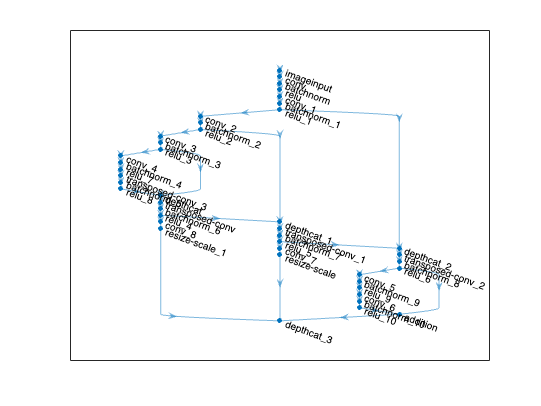

plot(net);